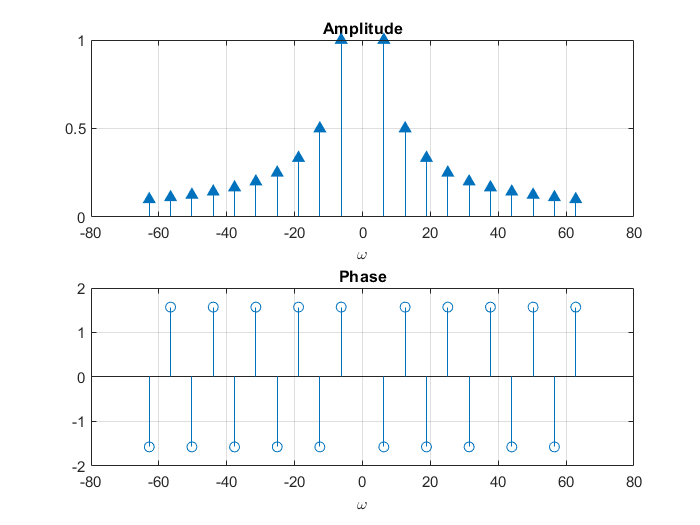

clear
n=20*pi;
omega=-n:2*pi:n;
X=zeros(1,length(omega));

k=-10:10;
for i=1:length(omega)     
    X(i)=(((-1)^k(i))/k(i));
end
x=X*1i;
magnitude=abs(x);
phase=angle(x);

phase(((length(x)-1)/2)+1)=inf;

figure


subplot(2,1,1)
stem(omega,magnitude,'^','filled')
title('Amplitude')
xlabel('\omega')
grid on

subplot(2,1,2)
stem(omega,phase)
title('Phase')
xlabel('\omega')
grid on 